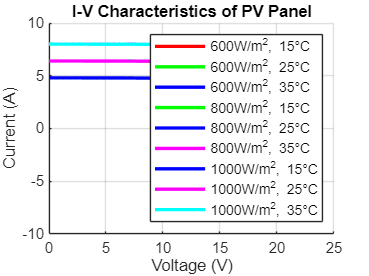

%% PV Supplied DC Motor with MPPT using RBF Neural Network
clc; clear; close all;

%% PV Panel Parameters
Isc = 8;               
Voc = 21;              
Vmpp = 17;             
Impp = 7.1;            
Ns = 72;              
Rs = 0.01;            
Rsh = 1000;            
T_stc = 25 + 273.15;       
k = 1.38e-23;          
q = 1.6e-19;           

%% Irradiation and Temperature Variations
G_values = [600, 800, 1000]; % in W/m²
T_values = [15, 25, 35] + 273.15; % in Kelvin

figure; hold on; grid on;
colors = {'r', 'g', 'b', 'm', 'c', 'k'};

for g = 1:length(G_values)
    for t = 1:length(T_values)
        G = G_values(g);
        T = T_values(t);

        Iph = Isc * (G / 1000);

        Vt = Ns * k * T / q;
        I0 = Isc / (exp(Voc / Vt) - 1);

        V_pv = linspace(0, Voc * (T_stc / T), 100); 
        I_pv = zeros(size(V_pv));

        % Newton-Raphson Method for I_pv
        for i = 1:length(V_pv)
            I = 0.1; % Small initial value to prevent zero state
            for j = 1:100
                f = Iph - I0 * (exp((V_pv(i) + I * Rs) / Vt) - 1) - (V_pv(i) + I * Rs) / Rsh - I;
                df = -I0 * (exp((V_pv(i) + I * Rs) / Vt) / Vt) - 1 - Rs / Rsh;
                I = I - f / df;
            end
            I_pv(i) = I;
        end

        % Plot I-V curve for each condition
        plot(V_pv, I_pv, 'Color', colors{mod(g+t-2, length(colors))+1}, 'LineWidth', 2);
    end
end

xlabel('Voltage (V)');
ylabel('Current (A)');
title('I-V Characteristics of PV Panel');
legend('600W/m^2, 15°C', '600W/m^2, 25°C', '600W/m^2, 35°C', ...
       '800W/m^2, 15°C', '800W/m^2, 25°C', '800W/m^2, 35°C', ...
       '1000W/m^2, 15°C', '1000W/m^2, 25°C', '1000W/m^2, 35°C');
hold off;


P_pv = V_pv .* I_pv;  

%% Quadratic Boost Converter Parameters
L1 = 50e-3;
L2 = 50e-3;
C = 20e-3;              
R_load = 10;           
V_in = Vmpp;           
time = 0:1e-5:0.5;     

%% Neural Network for MPPT (Using RBF)
input_data = [V_pv; I_pv];
output_data = P_pv / max(P_pv); 

num_neurons = 15; % Increased neurons for better learning
spread = 0.5;     % Reduced spread for better sensitivity
net = newrb(input_data, output_data, 0, spread, num_neurons);

NEWRB, neurons = 0, MSE = 0.0955246


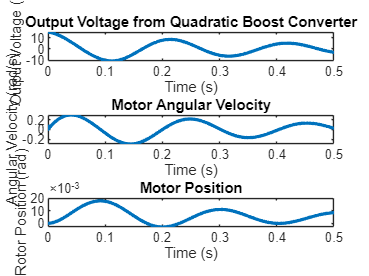


V_test = linspace(0, 21, 50);
I_test = 8 - 0.2 * V_test;
P_test = V_test .* I_test;
predicted = net([V_test; I_test]);

% **Interpolate Predicted Values and Normalize**
predicted_interp = interp1(linspace(0, 0.1, 50), predicted, time, 'linear');
predicted_interp = max(0.65, min(predicted_interp, 0.95));

%% Simulation of Boost Converter
V_out = zeros(size(time));
I_L1 = zeros(size(time));
I_L2 = zeros(size(time));

% Provide a small initial value to kick-start the process
V_out(1) = 15;
I_L1(1) = 0.1;
I_L2(1) = 0.1;

for t = 2:length(time)
    % Neural Network-Based MPPT Adjustment
    D = predicted_interp(t);
    
    % Boost Converter Equations (State-Space)
    I_L1(t) = I_L1(t-1) + (V_in - V_out(t-1) * D) * (time(t) - time(t-1)) / L1;
    I_L2(t) = I_L2(t-1) + (V_out(t-1) * (1 - D) - V_out(t-1)) * (time(t) - time(t-1)) / L2;
    V_out(t) = V_out(t-1) + ((I_L2(t-1) - V_out(t-1) / R_load) / C) * (time(t) - time(t-1));
end

%% DC Motor Parameters
J = 0.01;              
B = 0.2;               
Ke = 0.01;             
Kt = 0.01;             
Ra = 1;                
La = 0.5;              

theta = 0;
omega = 0;
Ia = 0;

theta_values = zeros(size(time));
omega_values = zeros(size(time));

% Provide a small starting angular velocity to simulate motion
omega_values(1) = 0.1;

for t = 2:length(time)
    V_motor = V_out(t); 
    
    Ia = (V_motor - Ke * omega) / Ra;
    omega = omega + (Kt * Ia - B * omega) * (time(t) - time(t-1)) / J;
    theta = theta + omega * (time(t) - time(t-1));
    
    theta_values(t) = theta;
    omega_values(t) = omega;
end

%% Results
figure;
subplot(3,1,1);
plot(time, V_out, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Output Voltage (V)');
title('Output Voltage from Quadratic Boost Converter');

subplot(3,1,2);
plot(time, omega_values, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Motor Angular Velocity');

subplot(3,1,3);
plot(time, theta_values, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Rotor Position (rad)');
title('Motor Position');